# 调整 SVM 分类器

使用 fitcsvm 的 'OptimizeHyperparameters' 名称-值对组参数来求得使交叉验证损失最小 的参数值。可使用的参数包括 'BoxConstraint'、'KernelFunction'、'KernelScale'、 'PolynomialOrder' 和 'Standardize'。有关示例，请参阅使用贝叶斯优化来优化 SVM 分类器拟合。 您也可以使用 bayesopt 函数，如Optimize Cross-Validated Classifier Using bayesopt中 所示。bayesopt 函数允许更加灵活地自定义优化。 您可以使用 bayesopt 函数优化任何参数，包括使用 fitcsvm 函数时不能优化的参数。

## 您还可以尝试根据以下方案手动调整分类器的参数：

将数据传递给 fitcsvm，并设置名称-值对组参数 'KernelScale','auto'。 假设经过训练的 SVM 模型称为 SVMModel。软件使用启发式过程来选择核尺度。 启发式过程使用二次抽样。因此，为了重现结果，在训练分类器之前， 请使用 rng 设置随机数种子。

通过将分类器传递给 crossval 以交叉验证分类器。 默认情况下，软件进行 10 折交叉验证。

将经过交叉验证的 SVM 模型传递给 kfoldLoss 以估计和保留分类误差。 重新训练 SVM 分类器，但调整 'KernelScale' 和 'BoxConstraint' 名称-值对组参数。 BoxConstraint - 一种策略是尝试框约束参数的等比数列。 例如，取依次增长 10 倍的 11 个值，从 1e-5 到 1e5。 增加 BoxConstraint 可能会减少支持向量的数量，但也会增加训练时间。 KernelScale - 一种策略是尝试基于原始核尺度缩放的 RBF sigma 参数的等比数列。 为此，请执行以下操作： 使用圆点表示法检索原始核尺度，例如 ks：ks = SVMModel.KernelParameters.Scale。 % 将原始核尺度的缩放值用作新的核尺度。例如，将 ks 乘以逐项递增 10 倍的 11 个值， 从 1e-5 到 1e5。 选择产生最低分类误差的模型。您可能需要进一步细化参数以获得更高的准确度。 从初始参数开始，执行另一个交叉验证步骤，这次使用因子 1.2。

## 用高斯核训练 SVM 分类器

此示例说明如何使用高斯核函数生成非线性分类器。 首先，在二维单位圆盘内生成一个由点组成的类， 在半径为 1 到半径为 2 的环形空间内生成另一个由点组成的类。 然后，使用高斯径向基函数核基于数据生成一个分类器。 默认的线性分类器显然不适合此问题，因为模型具有圆对称特性。 将框约束参数设置为 Inf 以进行严格分类，这意味着没有误分类的训练点。 其他核函数可能无法使用这一严格的框约束，因为它们可能无法提供严格的分类。 即使 rbf 分类器可以将类分离，结果也可能会过度训练。

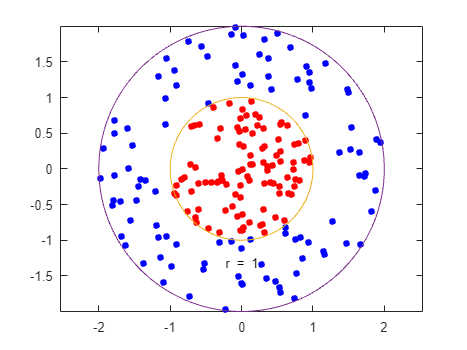

% 生成在单位圆盘上均匀分布的 100 个点。
% 为此，可先计算均匀随机变量的平方根以得到半径 r，并在 (0, 2π) 中均匀生成角度 t，
% 然后将点置于 (r cos(t), r sin(t)) 位置上。

rng(1); % For reproducibility
r = sqrt(rand(100,1)); % Radius
t = 2*pi*rand(100,1);  % Angle
data1 = [r.*cos(t), r.*sin(t)]; % Points
% 生成在环形空间中均匀分布的 100 个点。
% 半径同样与平方根成正比，这次采用从 1 到 4 均匀分布值的平方根。

r2 = sqrt(3*rand(100,1)+1); % Radius
t2 = 2*pi*rand(100,1);      % Angle
data2 = [r2.*cos(t2), r2.*sin(t2)]; % points
% 绘制各点，并绘制半径为 1 和 2 的圆进行比较。

figure;
plot(data1(:,1),data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1),data2(:,2),'b.','MarkerSize',15)
ezpolar(@(x)1);ezpolar(@(x)2);
axis equal
hold off

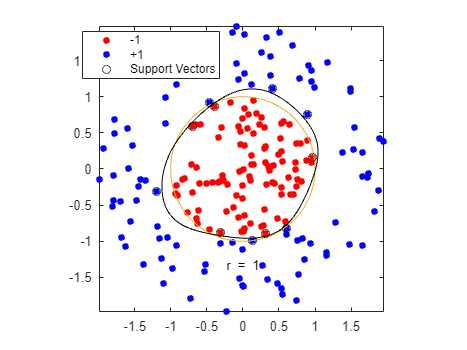

% Figure contains an axes. The axes contains 6 objects of type line, text.
% 将数据放在一个矩阵中，并建立一个分类向量。

data3 = [data1;data2];
theclass = ones(200,1);
theclass(1:100) = -1;
% 将 KernelFunction 设置为 'rbf'，
% BoxConstraint 设置为 Inf 以训练 SVM 分类器。
% 绘制决策边界并标记支持向量。

%Train the SVM Classifier
cl = fitcsvm(data3,theclass,'KernelFunction','rbf',...
    'BoxConstraint',Inf,'ClassNames',[-1,1]);

% Predict scores over the grid
d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(data3(:,1)):d:max(data3(:,1)),...
    min(data3(:,2)):d:max(data3(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(cl,xGrid);

% Plot the data and the decision boundary
figure;
h(1:2) = gscatter(data3(:,1),data3(:,2),theclass,'rb','.');
hold on
ezpolar(@(x)1);
h(3) = plot(data3(cl.IsSupportVector,1),data3(cl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

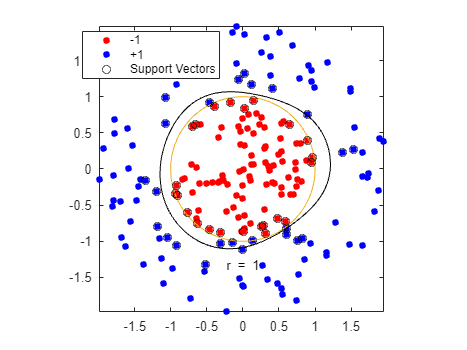

% Figure contains an axes. The axes contains 6 objects of type line, text, contour. 
% These objects represent -1, +1, Support Vectors.

% fitcsvm 生成一个接近半径为 1 的圆的分类器。差异是随机训练数据造成的。
% 使用默认参数进行训练会形成更接近圆形的分类边界，
% 但会对一些训练数据进行误分类。
% 此外，BoxConstraint 的默认值为 1，因此支持向量更多。

cl2 = fitcsvm(data3,theclass,'KernelFunction','rbf');
[~,scores2] = predict(cl2,xGrid);

figure;
h(1:2) = gscatter(data3(:,1),data3(:,2),theclass,'rb','.');
hold on
ezpolar(@(x)1);
h(3) = plot(data3(cl2.IsSupportVector,1),data3(cl2.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores2(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off